# soTaller Matlab 2

    Samuel David Negrete Lancheros

    Sara 

    Sofía Vera

clear
clc
load('PruebaEstereo.mat');

## Señal de audio en el tiempo

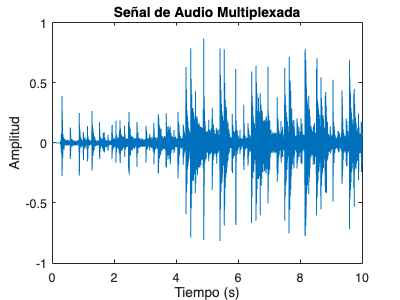

Fs = 120000;
t = (0:length(MUX)-1)/Fs; % Eje de tiempo
plot(t, MUX);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal de Audio Multiplexada');

## Transformada y su gráfica

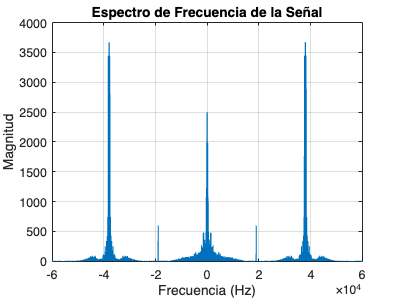

N = length(MUX); % Número de muestras
X = fft(MUX,N);    % Transformada de Fourier
X_shift = fftshift(X);
f = (-N/2:N/2-1)*(Fs/N); % Eje de frecuencias

% Graficar solo la mitad positiva
figure;
plot(f(1:N), abs(X_shift(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal');
grid on;

## Filtro pasabajos Lado izquierdo

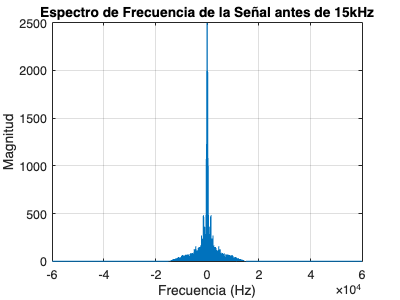

f0 = 15000;
H=(f>-f0).*(f<f0);
x_fil1 = X_shift.*H';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil1(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal antes de 15kHz');
grid on;

% jas=-15000:0.1:15000;
% D = 300000;

% plot((-60000:0.4:59999.6), abs(x_fil1t(1:300000)))

izq_t = ifft(fftshift(x_fil1));
izq_f = decimate(izq_t,4);
% izq_t = ifft(x_fil1t);
% izq_t = abs(izq_t);

## Filtro pasabanda centrado en 38kHz

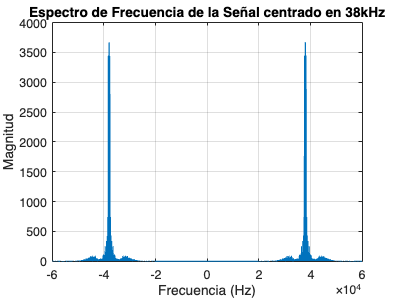

f1 = 20000;
f2 = 60000;
H1=(f>f1).*(f<f2);
H2=(f<-f1).*(f>-f2);
H3=H1+H2;

x_fil2 = X_shift.*H3';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil2(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal centrado en 38kHz');
grid on;


Y = ifft(x_fil2);


## Pasabanda de banda angosta centrado en 19kHz

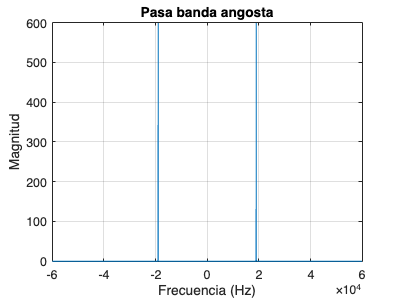

f3 = 18950;
f4 = 19050;
H1=(f>f3).*(f<f4);
H2=(f<-f3).*(f>-f4);
H3=H1+H2;
x_fil3 = X_shift.*H3';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil3(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Pasa banda angosta');
grid on;

## Multiplicar por el coseno 38kHz

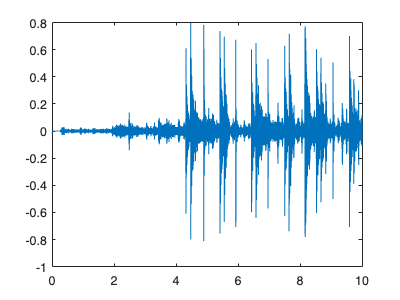

XCos = Y.*cos(2*pi*38000.*t');
X_cos = fft(XCos);    % Transformada de Fourier
X_cos_shift = fftshift(X_cos);

figure
plot(t(1:N), (XCos(1:N)));

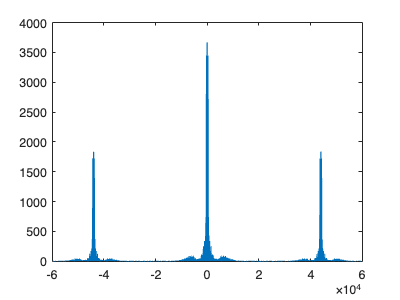

figure
plot(f(1:N), abs(X_cos(1:N)));

## Filtro 15kHz

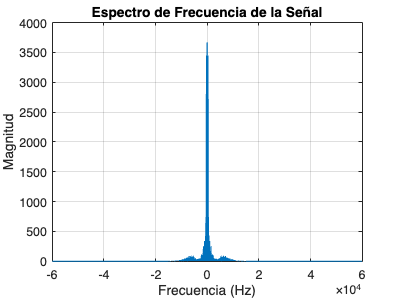

f0 = 15000;
H=(f>-f0).*(f<f0);
der_fil = X_cos.*H';

% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(der_fil(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal');
grid on;


derecha = ifft(der_fil); %Transformada no centrada
der_t = ifft(fftshift(der_fil)); % Transformada inversa de Fourier
der_f = decimate(der_t,4);
matriz = [izq_f , der_f];


## **Multiplexor**

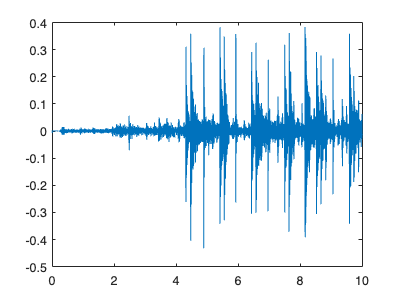

%Derecho
d_cos = derecha.*cos(2*pi*38000.*t');
td_cos = fft(d_cos); %Transformada de Fourier

figure
plot(t(1:N), (der_t(1:N)));

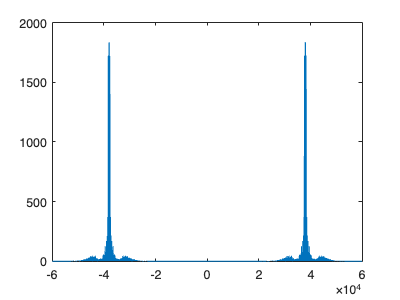

figure
plot(f(1:N), abs(td_cos(1:N)));

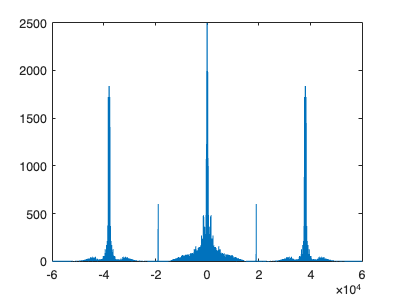



%SUMA DE SEÑALES
mt = x_fil1 + td_cos + x_fil3;
figure
plot(f(1:N), abs(mt(1:N)));

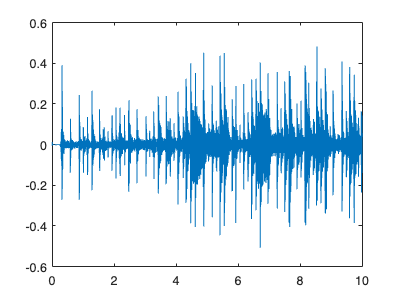


%Señal a tiempo discreto
trans_mt = ifft(fftshift(mt));
figure
plot(t(1:N), (trans_mt(1:N)));